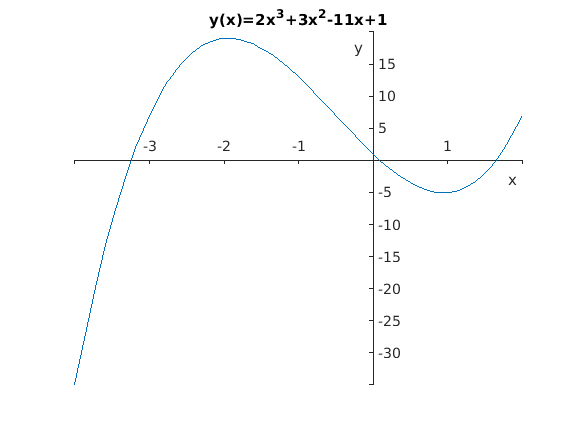

%1)
clear
syms y(x) y_2(x);

y(x) = 2*x^3 + 3*x^2 -11*x + 1;

fplot(y, [-4 2])

%beautifying
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
xlabel("x");
ylabel("y");
box off;
title("y(x)=2x^{3}+3x^{2}-11x+1")


%finding y intercept
y(0)

$$ans = 1$$


%finding turning points
eval(solve(diff(y(x),x),x))

ans =    -1.9434
    0.9434



%finding y coordinates of turning points
eval(y(0.9434))

ans = -5.0281

eval(y(-1.9434))

ans = 19.0281


%checking if second derivative of turning point is positive or negative
y_2(x) = diff(diff(y,x),x);
eval(y_2(0.94)) %positive results infers a localminima

ans = 17.2800

eval(y_2(-1.94)) %negative result infers a local maxima

ans = -17.2800

%2)
clear
syms y(x) y_1(x) y_2(x);

%declaring equation
y(x) = x^3 + 2*x^2 -6*x - 2

$$y(x) = x^{3}+2\,x^{2}-6\,x-2$$


%finding turning points
eval(solve(diff(y,x)==0,x))

ans =    -2.2301
    0.8968



%finding the y coordinates of the turning points
eval(y(-2.2301))

ans = 10.2362

eval(y(0.8968))

ans = -5.0510


%finding if turning points are local maxima or minma
y_1(x) = diff(y(x),x);
y_2(x) = diff(y_1(x));

eval(y_2(-2.2301)) % negative value infers local maxima

ans = -9.3806

eval(y_2(0.8968)) % positive value infers local minima

ans = 9.3808

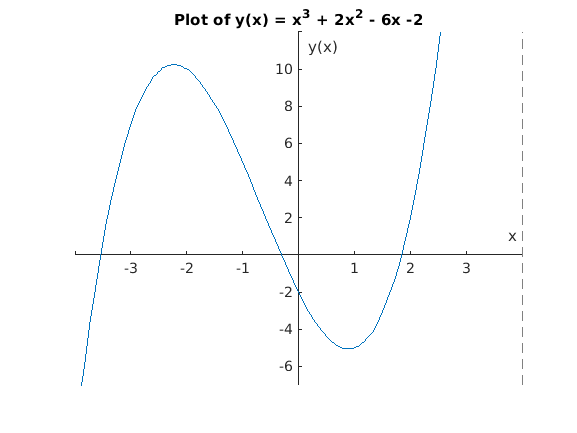


%plotting to ensure numbers seem correct
%plotting y(x) and setting ranges so that both turning points are visible
fplot(y, [-4 4])
ylim([-7 12])

%beautifying
ax=gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%adding chart labels
ylabel("y(x)")
xlabel("x")
title("Plot of y(x) = x^{3} + 2x^{2} - 6x -2")


%evaluating functions radius curvature
num = (1 + (y_1(0))^2)^(3/2);
den = y_2(0);
p = num/den;
eval(p)

ans = 56.2656

%3)
clear
syms F(n) F_1(n) F_2(n)

%declaring equation and differentiating
F(n) = (180000 - 1200*n - 45*n^2 +n^3) / 8000;
F_1(n) = diff(F,n);
F_2(n) = diff(F_1,n);

%calculating turning points
eval(solve(F_1(n)==0,n))

ans =    -10
    40



%checking for nature of turning points
eval(F_2(-10)) %negative result suggests a maxima

ans = -0.0188

eval(F_2(40)) %positive result suggests a minima

ans = 0.0188

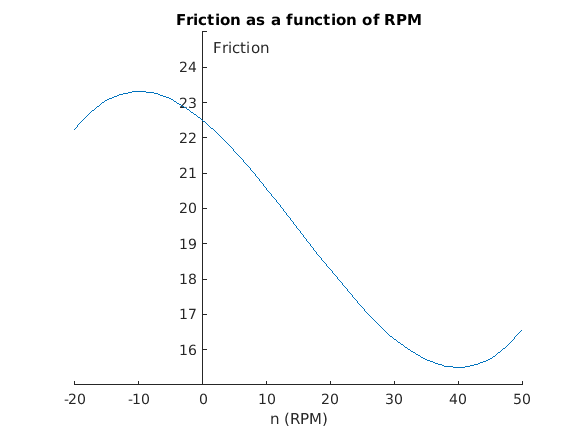


%plotting graph to check results make sense
fplot(F, [-20 50])
ylim([15 25])

%beautifying graph
ax=gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

xlabel("n (RPM)")
ylabel("Friction")
title("Friction as a function of RPM")

%5)
clear
syms l(O);

l(O) = 4/cos(O) + 2/sin(O)

$$l(O) = \frac{4}{\cos\left(\text{O}\right)}+\frac{2}{\sin\left(\text{O}\right)}$$

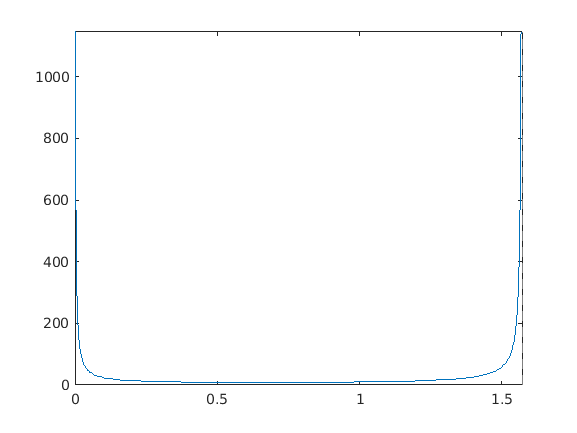


fplot(l, [0 pi/2])